# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 1 textures.
***Scene parsed.


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

thisR

thisR =   recipe with properties:

            camera: [1×1 struct]
           sampler: [1×1 struct]
              film: [1×1 struct]
            filter: []
        integrator: [1×1 struct]
          renderer: []
            lookAt: [1×1 struct]
             scale: [0×3 double]
             world: {5×1 cell}
            lights: {1×0 cell}
    transformTimes: []
         inputFile: 'C:\iset\iset3d\data\V3\sphere\sphere.pbrt'
        outputFile: 'C:\iset\iset3d\local\sphere\sphere.pbrt'
      renderedFile: ''
           version: 3
         materials: [1×1 struct]
          textures: [1×1 struct]
            assets: [1×1 tree]
          exporter: 'C4D'
             media: []
          metadata: []
         recipeVer: 2
           verbose: 2


## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light','add',pointLight);

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Write the recipe, render it, and show it

piWrite(thisR);

Overwriting PBRT file C:\iset\iset3d\local\sphere\sphere.pbrt


In this example, we use a pinhole camera.  Thus, we are rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file C:\iset\iset3d\local\sphere\sphere_depth.pbrt
Docker command
	docker run -ti --rm -w /sphere -v C:/iset/iset3d/local/sphere:/sphere vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/sphere.dat sphere.pbrt
*** Rendering time for sphere:  5.7 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.
Docker command
	docker run -ti --rm -w /sphere -v C:/iset/iset3d/local/sphere:/sphere vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/sphere_depth.dat sphere_depth.pbrt
*** Rendering time for sphere_depth:  4.7 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.


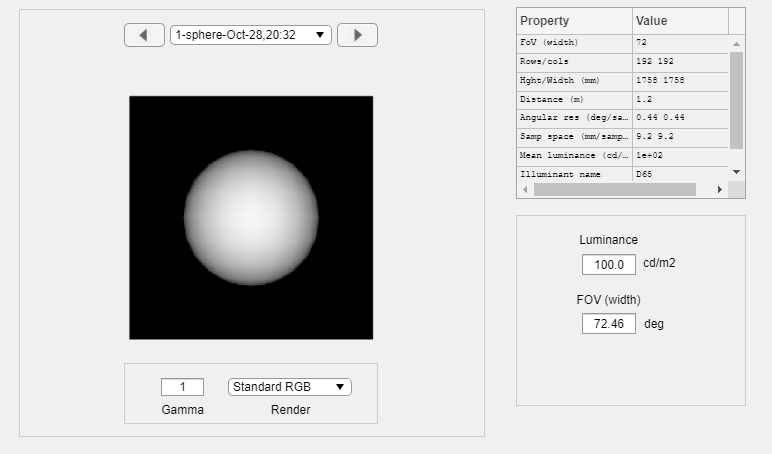

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

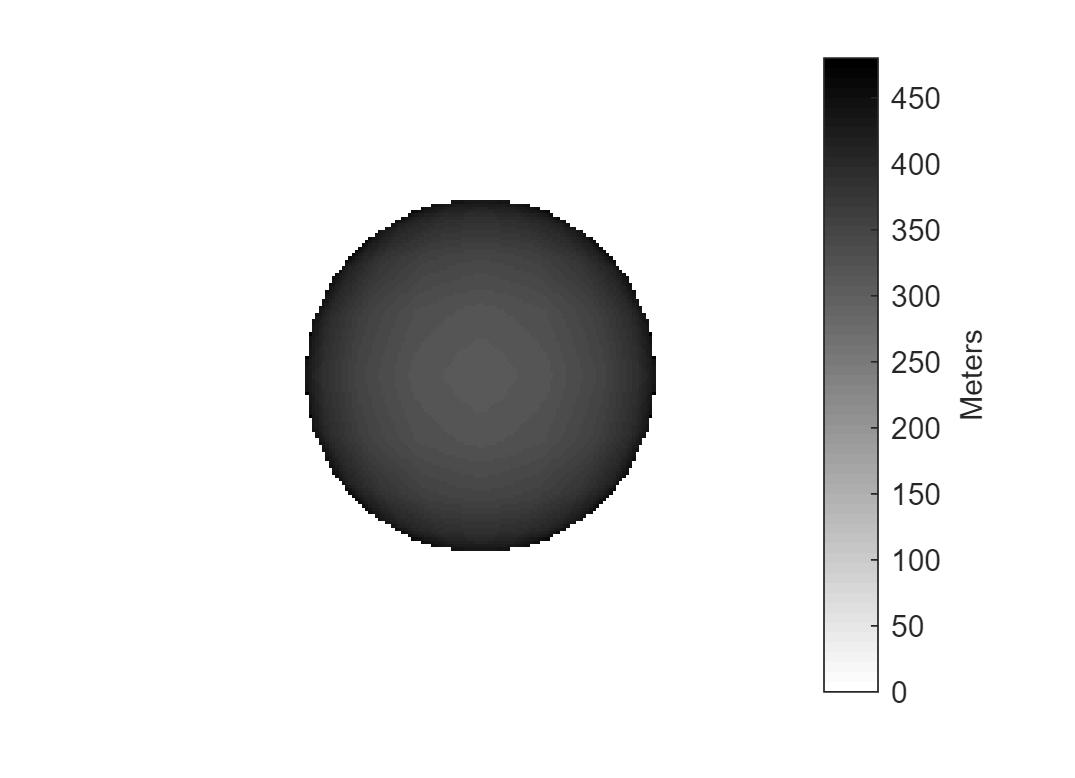

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

distantLight = piLightCreate('distant','type','distant',  'spd', [9000 0.001],  'cameracoordinate', true);
thisR.set('light','delete',pointLight.name);
thisR.set('light','add',distantLight);

This is an efficient way to Write, Render and Show without the separate calls.

Overwriting PBRT file C:\iset\iset3d\local\sphere\sphere.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm -w /sphere -v C:/iset/iset3d/local/sphere:/sphere vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/sphere.dat sphere.pbrt
*** Rendering time for sphere:  5.6 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.


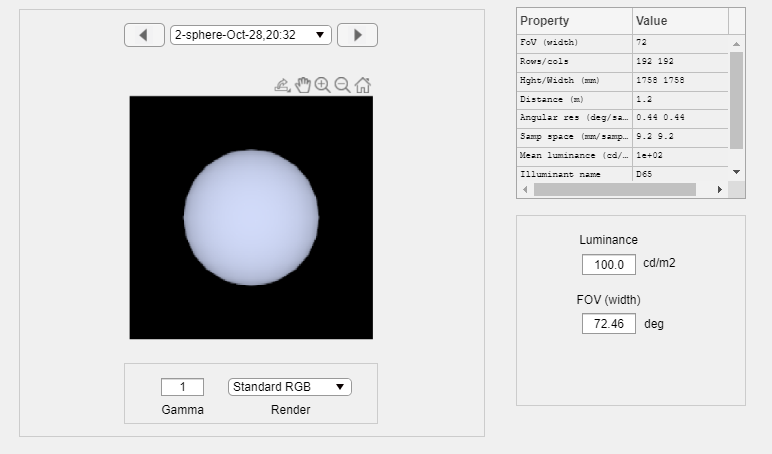

scene = piWRS(thisR);